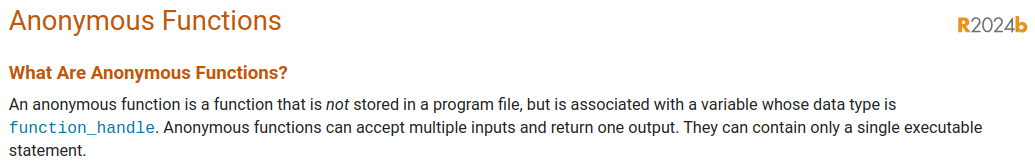

## Use-Case: Parameterizing a problem

Here is the (slightly modified) m-file from PMM.

% Solve the Lorentz system and plot the results.

% Run the ode solver
[T, M] = ode45(@rate_func, [0 30], [1 2 3]);

% plot the results
X = M(:,1);
Y = M(:,2);
Z = M(:,3);
plot(X, Y)
xlabel('X')
ylabel('Y')

function res = rate_func(t, V)
    % unpack the state vector
    x = V(1);
    y = V(2);
    z = V(3);

    % set the parameters
    sigma = 10;
    b = 8/3;
    r = 28;

    % compute the derivatives
    dxdt = sigma * (y-x);
    dydt = x * (r-z) - y;
    dzdt = x*y - b*z;

    % pack the results in a column vector
    res = [dxdt; dydt; dzdt];
end

### Adding user-specified system parameters to the rate function

A limitation is that the constants are defined within the rate_func (within the scope of the function), so we can't programmatically change them.

What if we wanted to solve this for a number of different values of `sigma`, `b` and `r`?  How do we get the parameters into the rate function?

function res = rate_func_parameterized(t, V, sigma, b, r)
    res = [ sigma*(V(2)-V(1));
            V(1) * (r-V(3)) - V(2);
            V(1)*V(2) - b*V(3)];
end


This parameterizes the Lorenz model, but it no longer complies with the ODE sovler interface, because it has too many inputs!

Then wrap the parameterized function with an anonymous function - that complies with the solever interface:

sigma = 10;
b = 8/3;
r = 28;
lorenz_rate_handle = @(t,y) rate_func_parameterized(t, y, sigma, b, r);

[T, M] = ode45(lorenz_rate_handle, [0 30], [1 2 3]);
figure;
plot(M(:,1), M(:,2))

Now we can change the parameters on the fly.

figure;
sigmas = [2 5 10 19];
for ii = 1:length(sigmas)
    sigma = sigmas(ii);
    b = 8/3;
    r = 28;
    % Redifine the anonymous function with the new parameters
    lorenz_rate_handle = @(t,y) rate_func_parameterized(t, y, sigma, b, r);
    % Pass it to the solver
    [T, M] = ode45(lorenz_rate_handle, [0 30], [1 2 3]);
    subplot(2,2,ii)
    plot(M(:,1), M(:,2))
    title(sprintf("sigma = %.1f",sigma))
end
hold off